clear; close all;

# Tutorial: Reconstruction of Asteroid Vesta

This software is made available under the MIT license. See SONIC/LICENSE for details.

This live script illustrates the use of the Triangulation class in SONIC in a 3D structure reconstruction. The asteroid Vesta will be reconstructed from features extracted in the images of the Rc3b segment from a known camera pose. The image dataset can be found in** [1]**. For more information on the triangulation algorithms, please refer to** [2]**.

Direct link to image dataset:

[https://huggingface.co/datasets/travisdriver/astrovision-data](https://huggingface.co/datasets/travisdriver/astrovision-data)

### Load Cameras and Tracks

This example will start with the image features measured and the corresponding camera poses and information. Let us first load them.

load("+examples/+data/vesta_cam_poses.mat")
load("+examples/+data/vesta_points.mat")

### Triangulation

Once we have the poses and feature correspondences between images, we can triangulate. This is completed by considering each point measured from more than one camera position (which is required to perform triangulation). Using the known camera poses, we can then use the SONIC class triangulation method, `triangulate()`. The triangulate method offers three approaches to triangulation: the direct linear transform (DLT), the midpoint algorithm, or Linear Optimal Sine Triangulation (LOST). For more information on the trangulate method, we can call `help` on the method (as with all other SONIC methods). For this implementation, we will use LOST and compute the covariance as well.

help sonic.Triangulation.triangulate

  [rI, cov_r] = triangulate(x_C, p_I, attitudes, method, cov_x, compute_cov)
    Triangulate using the specified method.
 
    References:
    - [1] S. Henry and J. A. Christian. Absolute Triangulation
    Algorithms for Space Exploration. JGCD (2023).
    https://doi.org/10.2514/1.G006989
 
    Inputs:
        - x_C (sonic.Points2): image_plane coordinates 
          (equivalent of K^-1 * pixel coordinate)
        - p_I  (sonic.Points3): respective 3D position objects
          that are used to triangulate (resection) OR position of
          the respective cameras (intersection)
        - attitudes
            - (nx1 sonic.Attitude): attitudes of the cameras
    
            OR
 
            - (1x1 sonic.Attitude): then all cameras have 
              the same attitude
        - method (string): "midpoint", "DLT", or "LOST"
        - cov_x (OPTIONAL)
            - DEFAULT: unit variance
            - (1x1 double): isotropic v

To begin, we determine how many points have been observed and preallocate space for the resulting triangulated positions and covariances. Additionally, the measurement variance is set to one pixel.

n_points = length(Tracks);

r_all = NaN(3, n_points);
std_all = NaN(1, n_points);

var_x = 1/K(1,1);

Now, for each measured point, we extract all images that viewed this point. After ensuring that this point has been viewed from at least 2 different views, we can then collect the corresponding camera information including the position and attitude. Note that the position is stored in a SONIC `Points3` object and the attitude is stored in a SONIC `Attitude` object. Then the measured points are extracted and stored as a SONIC `Points2` object. These representations of points and attitudes as SONIC objects are useful, because they contain precomputed information about your object. For more information, run `help` on the object constructors to view their headers.

With all the information gathered, we then use `sonic.Triangulation.triangulate()` method to calculate the estimated position and associated covariance of the measured point. This method takes in the measured points, camera positions and attitudes, and a specification of which algorithm to use. Here we choose the Linear Optimal Sine Triangulation (LOST). In addition to triangulating the position, we can also indicate that we want to compute the covariance or not. This is done by setting the last input, `compute_cov,` to true.

tic
for ii = 1:n_points
    viewIds = Tracks(ii).viewIds();

    if length(viewIds) >= 2
        pI_all = sonic.Points3(cam_positions(:, viewIds));

        attitudes = sonic.Attitude.empty;
        for jj = 1:length(viewIds)
            attitudes(end+1) = sonic.Attitude(cam_rots(:,:,viewIds(jj)));
        end

        xC_all = sonic.Points2(Tracks(ii).meas');

        [r_ii, Prr_ii] = sonic.Triangulation.triangulate( ...
            xC_all, pI_all, attitudes, 'LOST', var_x, true);
        r_all(:,ii) = r_ii.r3;
        std_all(:,ii) = sqrt(trace(Prr_ii));
    end
end
toc

Elapsed time is 9.847269 seconds.


### Plot the 3D reconstruction of Vesta

The benefit of calculating the covariances is that we can filter some of the triangulated points which have very high covariance. In this visualization, we will not include those for a cleaner structure. In the first figure, we show the camera positions and triangulated points for clarity, and in the second figure we show only the triangulated points.

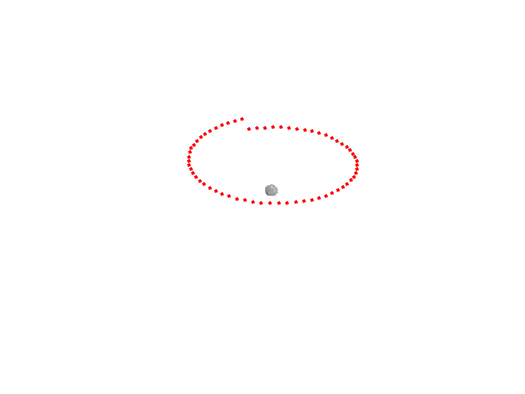

cond_1 = ~isnan(r_all(1,:));
cond_2 = std_all < 100;

cond_all = cond_1 & cond_2;

figure(1)
pcshow(cam_positions', 'r', MarkerSize=75)
hold on
pcshow(r_all(:, cond_all)', colors(cond_all,:), MarkerSize=75)
hold off

axlim = 6e3;
xlim([-axlim, axlim])
ylim([-axlim, axlim])
zlim([-axlim, axlim])
set(gcf,'color','white')
set(gca,'visible','off')

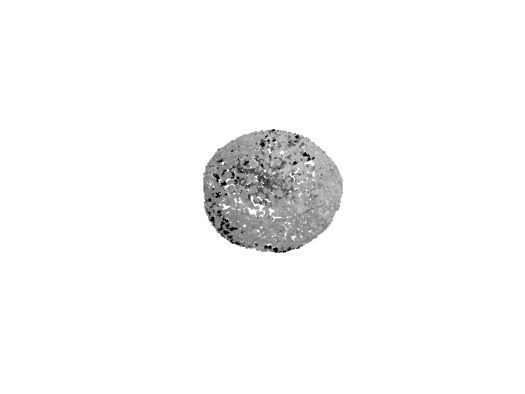

figure(2)
pcshow(r_all(:, cond_all)', colors(cond_all,:), MarkerSize=75)

axlim = 4e2;
xlim([-axlim, axlim])
ylim([-axlim, axlim])
zlim([-axlim, axlim])
set(gcf,'color','white')
set(gca,'visible','off')

disp("number of points in structure = " + sum(cond_all))

number of points in structure = 11538


### References

**[1]** Driver, T., Skinner, K. A., Dor, M., & Tsiotras, P. (2023).  AstroVision: Towards autonomous feature detection and description for  missions to small bodies using deep learning. *Acta Astronautica*, *210*, 393-410.

**[2]** S. Henry and J. A. Christian, “Absolute Triangulation Algorithms for Space Exploration,” Journal of Guidance, Control, and Dynamics, Vol. 46, Jan. 2023, p. 21–46, 10.2514/1.g006989